# PDSCH Waveform generation

saveFiles = true;
outPath = fileparts(matlab.desktop.editor.getActiveFilename);
disp(outPath);

/Users/shahab/code/Fireball/OpenSource/onGithub/Tests/Wireless/NewProject/OnGit/neoradium/Playground/CompareWithMatlab/PDSCH/MatlabFiles


## Carrier Configuration

Specify the number of transmit antennas and create a carrier configuration object. This object controls the size of the resource grid. For simplicity, use the default carrier configuration object.

nTxAnts = 4;
carrier = nrCarrierConfig;
carrier.NStartGrid = 1;
carrier.SubcarrierSpacing=30

carrier =   nrCarrierConfig with properties:

                NCellID: 1
      SubcarrierSpacing: 30
           CyclicPrefix: 'normal'
              NSizeGrid: 52
             NStartGrid: 1
                  NSlot: 0
                 NFrame: 0
    IntraCellGuardBands: [0×2 double]

   Read-only properties:
         SymbolsPerSlot: 14
       SlotsPerSubframe: 2
          SlotsPerFrame: 20


## PDSCH and PDSCH DM-RS Configuration

Create a PDSCH configuration object. This object specifies PDSCH-related parameters. Specify 16-QAM modulation, two layers, and full band allocation. This configuration maps the PDSCH into a bandwidth part (BWP) of equal size to the carrier. You can also use this object to specify other time-allocation parameters and DM-RS settings.

pdsch = nrPDSCHConfig;
pdsch.Modulation = "16QAM";
pdsch.NumLayers = 2;
pdsch.PRBSet = 0:carrier.NSizeGrid-1; % Full band allocation
pdsch.VRBToPRBInterleaving = 1;
pdsch.PRBSetType = "PRB";             % NOTE: Remark out this line if using Matlab 2022b or older

Display the PDSCH and PDSCH DM-RS parameters.

pdsch

pdsch =   nrPDSCHConfig with properties:

                NSizeBWP: []
               NStartBWP: []
             ReservedPRB: {[1×1 nrPDSCHReservedConfig]}
              ReservedRE: []
              Modulation: '16QAM'
               NumLayers: 2
             MappingType: 'A'
        SymbolAllocation: [0 14]
                  PRBSet: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51]
              PRBSetType: 'PRB'
    VRBToPRBInterleaving: 1
           VRBBundleSize: 2
                     NID: []
                    RNTI: 1
                    DMRS: [1×1 nrPDSCHDMRSConfig]
              EnablePTRS: 0
                    PTRS: [1×1 nrPDSCHPTRSConfig]

   Read-only properties:
            NumCodewords: 1


pdsch.DMRS

ans =   nrPDSCHDMRSConfig with properties:

      DMRSConfigurationType: 1
         DMRSReferencePoint: 'CRB0'
          DMRSTypeAPosition: 2
     DMRSAdditionalPosition: 0
                 DMRSLength: 1
            CustomSymbolSet: []
                DMRSPortSet: []
                   NIDNSCID: []
                      NSCID: 0
    NumCDMGroupsWithoutData: 2
            DMRSDownlinkR16: 0

   Read-only properties:
                  CDMGroups: [0 0]
                DeltaShifts: [0 0]
           FrequencyWeights: [2×2 double]
                TimeWeights: [2×2 double]
    DMRSSubcarrierLocations: [6×2 double]
                 CDMLengths: [2 1]


## PDSCH Generation

Generate indices to map the PDSCH to the grid.

[pdschIndices,pdschInfo] = nrPDSCHIndices(carrier,pdsch);

Generate and map random PDSCH bits to PDSCH symbols. The input argument `pdschInfo.G` specifies the bit capacity of the PDSCH, which is the length of the codeword from the channel coding stages. `pdschInfo.G` takes into account the resource elements (REs) available for PDSCH transmission. For simplicity, this example does not include downlink shared channel (DL-SCH) modeling. 

% Unremark this to generate random bits

if saveFiles
    pdschBits = randi([0 1],pdschInfo.G,1);
    save(strcat(outPath,'/pdschBits.mat'),'pdschBits');
else
    % Load random bits from file for deterministic results
    pdschBits = load(strcat(outPath,'/pdschBits.mat')).pdschBits;
end


Generate PDSCH symbols. The PDSCH symbols are stored in a matrix of size $N_s$-by-$\nu$, where $N_s$ is the number of symbols and $\nu$ is the number of layers.

pdschSymbols = nrPDSCH(carrier,pdsch,pdschBits);
size(pdschSymbols)

ans =         8112           2


if saveFiles 
    save(strcat(outPath,'/pdschSymbols.mat'),'pdschSymbols');
end
% First 20 data Symbols:
pdschSymbols(1:20,1)

ans =   -0.3162 + 0.3162i
  -0.9487 + 0.9487i
  -0.3162 + 0.3162i
   0.3162 - 0.3162i
   0.9487 - 0.3162i
  -0.3162 + 0.9487i
  -0.9487 - 0.9487i
   0.9487 + 0.3162i
   0.9487 + 0.9487i
   0.3162 - 0.3162i


## PDSCH DM-RS Generation

Generate DM-RS symbols and indices.

dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);

if saveFiles 
    save(strcat(outPath,'/dmrsSymbols.mat'),'dmrsSymbols');
end
% First 10 DMRS Symbols:
dmrsSymbols(1:10,1)

ans =    0.7071 - 0.7071i
   0.7071 + 0.7071i
   0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i


## MIMO Precoding and Mapping to the Resource Grid

Apply precoding. Channel measurements determine the precoding weights (also referred to as *beamforming weights*). However, this example does not model the propagation channel. This example assumes that the precoding weights are known.

% Precoding weights
W = fft(eye(nTxAnts))/sqrt(nTxAnts);              % Unitary precoding matrix
w = W(1:pdsch.NumLayers,:)/sqrt(pdsch.NumLayers); % Normalize by number of layers
size(pdschSymbols)

ans =         8112           2


size(w)

ans =      2     4


Precode the PDSCH symbols.

pdschSymbolsPrecoded = pdschSymbols*w;
size(pdschSymbolsPrecoded)

ans =         8112           4


Generate an empty resource grid. This grid spans one slot.

pdschGrid = nrResourceGrid(carrier,nTxAnts);
size(pdschGrid)

ans =    624    14     4


[~,pdschAntIndices] = nrExtractResources(pdschIndices,pdschGrid);
pdschGrid(pdschAntIndices) = pdschSymbolsPrecoded;

Precode and map the DM-RS symbols to the grid. Similar to the PDSCH indices, the DM-RS indices refer to layers. To convert these layers to multiantenna indices, use the `nrExtractResources` function again.

% PDSCH DM-RS precoding and mapping
for p = 1:size(dmrsSymbols,2)
    [~,dmrsAntIndices] = nrExtractResources(dmrsIndices(:,p),pdschGrid);
    pdschGrid(dmrsAntIndices) = pdschGrid(dmrsAntIndices) + dmrsSymbols(:,p)*w(p,:);
end
if saveFiles 
    save(strcat(outPath,'/pdschGrid.mat'),'pdschGrid');
end
pdschGrid(1:10,1,1)

ans =    0.2236 + 0.4472i
  -0.2236 + 0.2236i
  -0.4472 + 0.2236i
   0.4472 + 0.2236i
   0.6708 - 0.2236i
   0.2236 + 0.2236i
  -0.6708 + 0.0000i
   0.2236 + 0.4472i
   0.4472 + 0.2236i
   0.4472 - 0.2236i


Display the resource grid for the first antenna.

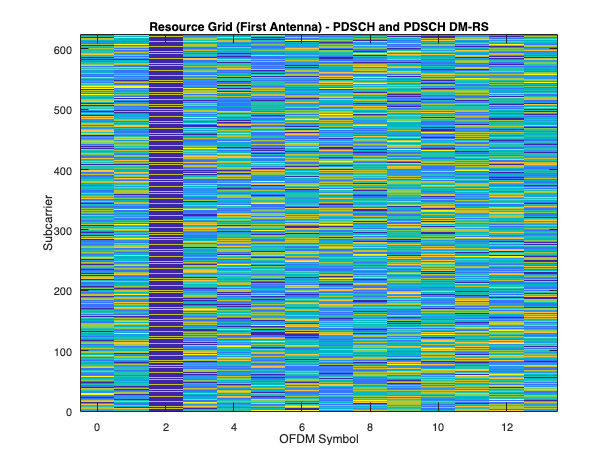

imagesc([0 carrier.SymbolsPerSlot-1],[0 carrier.NSizeGrid*12-1],abs(pdschGrid(:,:,1)));
axis xy;title("Resource Grid (First Antenna) - PDSCH and PDSCH DM-RS");
    xlabel("OFDM Symbol");ylabel("Subcarrier")

## OFDM Modulation

OFDM-modulate the resource grid and display the time-domain waveform for the first antenna.

[txWaveform,waveformInfo] = nrOFDMModulate(carrier,pdschGrid);
save(strcat(outPath,'/txWaveform.mat'),'txWaveform');
txWaveform(1:10,1)

ans =    0.0091 + 0.0032i
   0.0105 + 0.0007i
  -0.0014 + 0.0021i
  -0.0019 + 0.0060i
   0.0111 + 0.0053i
   0.0150 - 0.0004i
   0.0033 - 0.0066i
  -0.0085 - 0.0111i
  -0.0107 - 0.0064i
  -0.0072 + 0.0088i


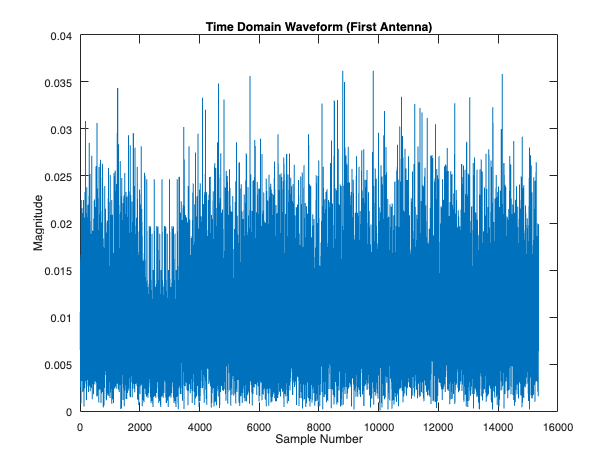

plot(abs(txWaveform(:,1)));title("Time Domain Waveform (First Antenna)");xlabel("Sample Number");ylabel("Magnitude")

The `waveformInfo` output contains information about the time-domain waveform, such as the sampling rate.

waveformInfo

waveformInfo = struct with fields:
                   Nfft: 1024
             SampleRate: 30720000
    CyclicPrefixLengths: [88 72 72 72 72 72 72 72 72 72 72 72 72 72 88 72 72 72 72 72 72 72 72 72 72 72 72 72]
          SymbolLengths: [1112 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1112 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096]
              Windowing: 36
           SymbolPhases: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
         SymbolsPerSlot: 14
       SlotsPerSubframe: 2
          SlotsPerFrame: 20
